# 5.2 IIR 滤波器的直接型结构：直接 I 型、直接 II 型（典范型）、转置型——同一个差分方程的三种实现

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 系统：教材例 5.1 / 例 5.2 的 IIR，先把分母首项归一

b = [1 -3 11 27 18]/16; a = [16 12 2 -4 -2]/16;   % H(z)=Σb_r z^-r / (1 − Σ a_k z^-k)，a(1)=1
br = b; ak = -a(2:end);                            % 教材记法：y(n)=Σ_{r=0}^{M} b_r x(n−r) + Σ_{k=1}^{N} a_k y(n−k)
Nh = 30; delta = [1 zeros(1, Nh-1)]; u = ones(1, Nh);
hRef = filter(b, a, delta); sRef = filter(b, a, u);   % 以内置 filter 为基准

## 演示1：直接 I 型——两条延时链，先算零点部分再算极点部分（教材图 5.2.2）

h1 = direct1(br, ak, delta); s1 = direct1(br, ak, u);

## 演示2：直接 II 型（典范型）——交换次序后共用一条延时链 w(n)（教材式 (5.2.4)、图 5.2.5）

[h2, w2] = direct2(br, ak, delta); s2 = direct2(br, ak, u);

## 演示3：转置型——把直接 II 型的流图反向：支路反向、输入输出互换（教材图 5.2.7）

h3 = transposed(br, ak, delta); s3 = transposed(br, ak, u);
errs = [max(abs(h1 - hRef)), max(abs(h2 - hRef)), max(abs(h3 - hRef)), max(abs(s1 - sRef)), max(abs(s2 - sRef)), max(abs(s3 - sRef))];

## 演示4：零极点与稳定性；三种结构的延时单元个数

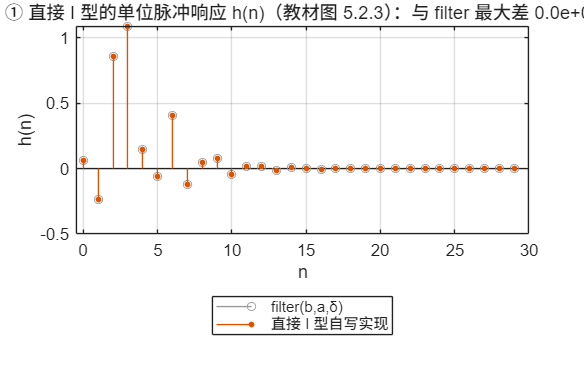

z0 = roots(b); p0 = roots(a); maxPole = max(abs(p0));
M = numel(br) - 1; N = numel(ak);
delays = [M + N, max(M, N), max(M, N)];            % 直接 I 型 M+N；直接 II 型与转置型 max(M,N)
mults = (M + 1 + N)*[1 1 1];

if ~LIVE, f1 = figure('Name','02 IIR 直接型','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(0:Nh-1, hRef, 'MarkerSize', 5, 'Color', [0.6 0.6 0.6]); hold on;
stem(0:Nh-1, h1, 'filled', 'MarkerSize', 3); grid on; xlim([-0.5 Nh]);
title(sprintf('① 直接 I 型的单位脉冲响应 h(n)（教材图 5.2.3）：与 filter 最大差 %.1e', errs(1)));
xlabel('n'); ylabel('h(n)'); legend('filter(b,a,δ)', '直接 I 型自写实现');

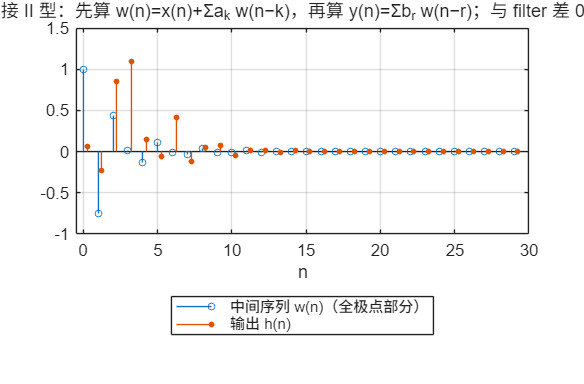

newpanel(); stem(0:Nh-1, w2, 'MarkerSize', 4); hold on; stem((0:Nh-1)+0.25, h2, 'filled', 'MarkerSize', 3); grid on; xlim([-0.5 Nh]);
title(sprintf('② 直接 II 型：先算 w(n)=x(n)+Σa_k w(n−k)，再算 y(n)=Σb_r w(n−r)；与 filter 差 %.1e', errs(2)));
xlabel('n'); legend('中间序列 w(n)（全极点部分）', '输出 h(n)');

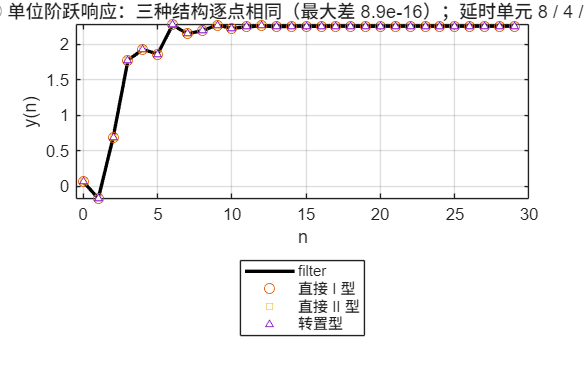

newpanel(); plot(0:Nh-1, sRef, 'k-', 'LineWidth', 2); hold on;
plot(0:Nh-1, s1, 'o', 'MarkerSize', 6); plot(0:Nh-1, s2, 's', 'MarkerSize', 5); plot(0:Nh-1, s3, '^', 'MarkerSize', 4, 'MarkerFaceColor', 'auto');
grid on; xlim([-0.5 Nh]); xlabel('n'); ylabel('y(n)');
title(sprintf('③ 单位阶跃响应：三种结构逐点相同（最大差 %.1e）；延时单元 %d / %d / %d 个', max(errs(4:6)), delays));
legend('filter', '直接 I 型', '直接 II 型', '转置型');

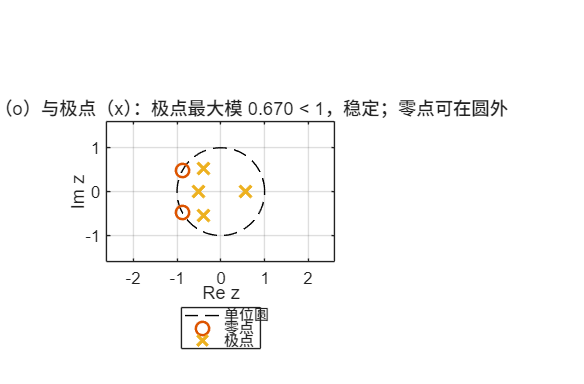

newpanel(); th = linspace(0, 2*pi, 400); plot(cos(th), sin(th), 'k--'); hold on; axis equal; grid on;
plot(real(z0), imag(z0), 'o', 'MarkerSize', 8, 'LineWidth', 1.5); plot(real(p0), imag(p0), 'x', 'MarkerSize', 10, 'LineWidth', 2);
xlim([-2.6 2.6]); ylim([-1.6 1.6]); xlabel('Re z'); ylabel('Im z');
title(sprintf('④ 零点（o）与极点（x）：极点最大模 %.3f < 1，稳定；零点可在圆外', maxPole));
legend('单位圆', '零点', '极点');

if ~LIVE, sgtitle('直接型：同一差分方程，两条延时链（I 型）→ 一条（II 型）→ 反向（转置型），输出完全一样'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '02-iir-direct.png'), 'Resolution', 150); end

## 教师核验

assert(all(errs < 1e-12), '三种结构应与 filter 逐点一致');
assert(maxPole < 1, '例 5.1 应当稳定');
assert(isequal(delays, [8 4 4]), '延时单元个数不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'b_normalized', b, 'a_normalized', a, 'h_first8', hRef(1:8), 'err_direct1_h', errs(1), 'err_direct2_h', errs(2), 'err_transposed_h', errs(3), ...
    'err_step_max', max(errs(4:6)), 'pole_radius', abs(p0).', 'zero_radius', abs(z0).', 'delays_I_II_T', delays, 'multipliers', mults(1), 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-iir-direct.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

       matlab_version: '25.2.0.3360999 (R2025b) Update 7'
               run_at: '2026-09-18 20:50:40'
         b_normalized: [0.0625 -0.1875 0.6875 1.6875 1.1250]
         a_normalized: [1 0.7500 0.1250 -0.2500 -0.1250]
             h_first8: [0.0625 -0.2344 0.8555 1.0908 0.1492 -0.0637 0.4087 -0.1250]
        err_direct1_h: 0
        err_direct2_h: 0
     err_transposed_h: 0
         err_step_max: 8.8818e-16
          pole_radius: [0.5567 0.6701 0.6701 0.5000]
          zero_radius: [4.2707 4.2707 0.9934 0.9934]
        delays_I_II_T: [8 4 4]
          multipliers: 9
    all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results


## 本地函数：三种结构的逐样本实现（只用循环与加乘，对应流图里的每条支路）

function y = direct1(br, ak, x)
% 直接 I 型：x 的延时链（M 个）和 y 的延时链（N 个）
M = numel(br) - 1; N = numel(ak); xd = zeros(1, M); yd = zeros(1, N); y = zeros(size(x));
for n = 1:numel(x)
    y(n) = br(1)*x(n) + sum(br(2:end).*xd) + sum(ak.*yd);
    xd = [x(n) xd(1:end-1)]; yd = [y(n) yd(1:end-1)];
end
end

function [y, w] = direct2(br, ak, x)
% 直接 II 型：先极点部分 w(n)=x(n)+Σa_k w(n−k)，再零点部分 y(n)=Σb_r w(n−r)，共用一条延时链
M = numel(br) - 1; N = numel(ak); K = max(M, N);
brp = [br zeros(1, K-M)]; akp = [ak zeros(1, K-N)];
wd = zeros(1, K); y = zeros(size(x)); w = zeros(size(x));
for n = 1:numel(x)
    w(n) = x(n) + sum(akp.*wd);
    y(n) = brp(1)*w(n) + sum(brp(2:end).*wd);
    wd = [w(n) wd(1:end-1)];
end
end

function y = transposed(br, ak, x)
% 转置型：y(n)=b_0 x(n)+s_1；s_i ← b_i x(n) + a_i y(n) + s_{i+1}，s_{K+1}=0
M = numel(br) - 1; N = numel(ak); K = max(M, N);
brp = [br zeros(1, K-M)]; akp = [ak zeros(1, K-N)];
s = zeros(1, K+1); y = zeros(size(x));
for n = 1:numel(x)
    y(n) = brp(1)*x(n) + s(1);
    for i = 1:K, s(i) = brp(i+1)*x(n) + akp(i)*y(n) + s(i+1); end
end
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end